# Sample 3-5

## 平滑化／先鋭化処理

境界処理 

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image smoothing/sharpening

Boundary operation

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 配列のパディング

(Pad array)

- Zero padding

- Periodic extension

- Symmetric extension

% Pad size setting
padsize = 2;
%
A = randi(8,4)

A =      4     1     6     8
     6     2     4     3
     7     8     3     1
     4     3     3     1


% Zero padding
B = padarray(A,[padsize padsize],0,'both')

B =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     4     1     6     8     0     0
     0     0     6     2     4     3     0     0
     0     0     7     8     3     1     0     0
     0     0     4     3     3     1     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


% Periodic extension
C = padarray(A,[padsize padsize],'circular','both')

C =      3     1     7     8     3     1     7     8
     3     1     4     3     3     1     4     3
     6     8     4     1     6     8     4     1
     4     3     6     2     4     3     6     2
     3     1     7     8     3     1     7     8
     3     1     4     3     3     1     4     3
     6     8     4     1     6     8     4     1
     4     3     6     2     4     3     6     2


% Symmetric extension
D = padarray(A,[padsize padsize],'symmetric','both')

D =      2     6     6     2     4     3     3     4
     1     4     4     1     6     8     8     6
     1     4     4     1     6     8     8     6
     2     6     6     2     4     3     3     4
     8     7     7     8     3     1     1     3
     3     4     4     3     3     1     1     3
     3     4     4     3     3     1     1     3
     8     7     7     8     3     1     1     3


### サンプル画像の準備

(Preparation of sample image)

本サンプルで利用する画像データを収めたdata フォルダにパスをとおす。

Create a path to the data folder that contains images used in this sample.

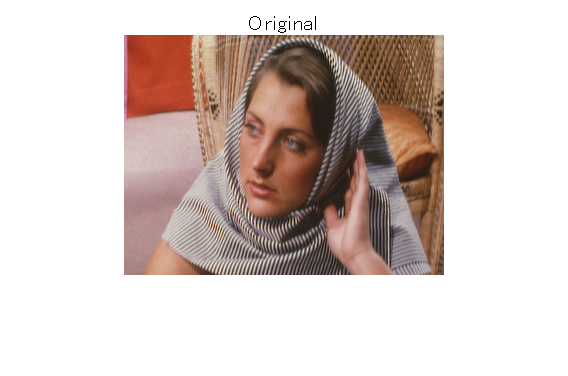

addpath('./data')
close
% Reading original image
I = im2double(imread('barbaraFaceRgb.tif'));
figure(1)
imshow(I)
title('Original')

### フィルタの設定

(Filter setting)

% Filter setting
hsize = 3;
f = fspecial('average',hsize);

### 零値拡張

(Zero padding)

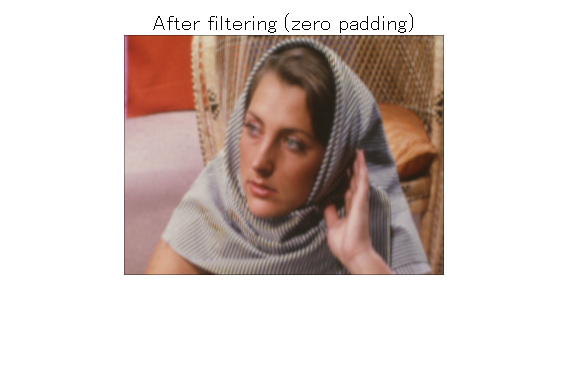

% Zero padding
Jz = imfilter(I,f);

% Show result
figure(2)
imshow(Jz)
title('After filtering (zero padding)')

### 周期拡張

(Periodic extension)

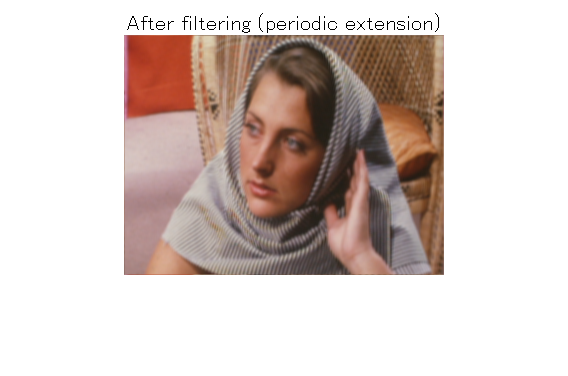

% Periodic extension
Jp = imfilter(I,f,'circular');

% Show result
figure(3)
imshow(Jp)
title('After filtering (periodic extension)')

### 対称拡張

(Symmetric extension)

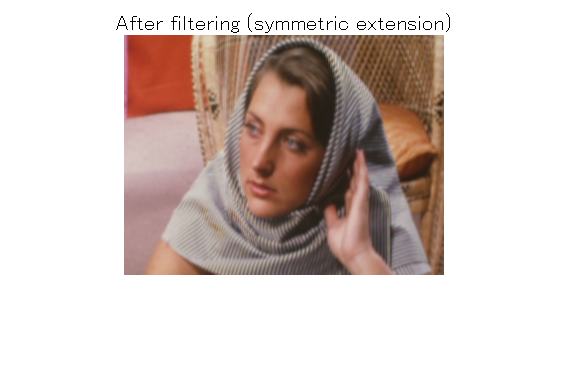

% Symmetric extension
Js = imfilter(I,f,'symmetric');

% Show result
figure(4)
imshow(Js)
title('After filtering (symmetric extension)')

### 結果の比較

(Comparison)

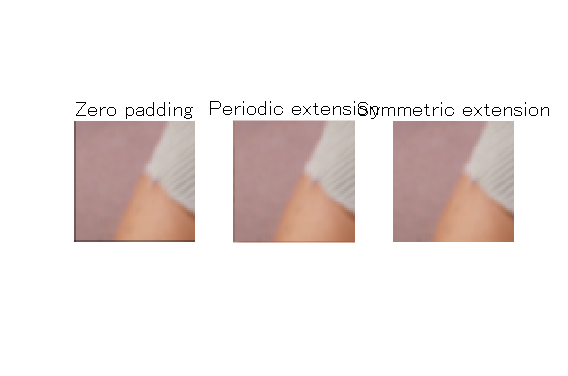

% Patch size
psize = 64;

% Zero padding
figure(5)
subplot(1,3,1)
imshow(Jz(end-psize+1:end,1:psize,:))
title('Zero padding')

% Periodic extension
subplot(1,3,2)
imshow(Jp(end-psize+1:end,1:psize,:))
title('Periodic extension')

% Zero padding
subplot(1,3,3)
imshow(Js(end-psize+1:end,1:psize,:))
title('Symmetric extension')

© Copyright, Shogo MURAMATSU, All rights reserved.